# Concrete Strength

Concrete mixtures have several variations. This data set is a case study for data visualization and exploration to predict the concrete compressive strength (MPa).

This case study is to determine the factors (inputs) that have correlation to the concrete compressive strength (output). Use visualization and exploration to gain an understanding of the data and make decisions about how it can be applied to predict strength. Use the data to determine data diversity, relationships, missing data, bad data, and factors that are important for regression. This case study uses data from [**concrete samples**](https://apmonitor.com/pds/uploads/Main/cement_strength.txt) that is also posted to [**Revisting a Concrete Strength Regression on Kaggle**](https://www.kaggle.com/maajdl/yeh-concret-data).

## Description

Concrete strength is affected by factors such as water to cement ratio, raw material quality, the ratio of coarse or fine aggregate, concrete age, concrete compaction, temperature, relative humidity, and other factors during the curing of the concrete. The data includes the following information for 1030 concrete samples.

**Input variable:**

- Cement: kg/m3 mixture

- Blast Furnace Slag: kg/m3 mixture

- Fly Ash: kg/m3 mixture

- Water: kg/m3 mixture

- Superplasticizer: kg/m3 mixture

- Coarse Aggregate: kg/m3 mixture

- Fine Aggregate: kg/m3 mixture

- Age: Day (1 to 365)

**Output variable:**

- Concrete compressive strength: MPa

## Activity 1: Data Visualization and Exploration

Use the first activity to complete the case study on data visualization and exploration.

% Import the data and read the first 10 rows
url = 'http://apmonitor.com/pds/uploads/Main/cement_strength.txt';
df = readtable(url);
df(1:20,:)

ans = 20×9 table
    cement    slag     flyash    water    superplasticizer    coarseaggregate    fineaggregate    age    csMPa
    ______    _____    ______    _____    ________________    _______________    _____________    ___    _____

      540         0      0        162           2.5                 1040               676         28    79.99
      540         0      0        162           2.5                 1055               676         28    61.89
    332.5     142.5      0        228             0                  932               594        270    40.27
    332.5     142.5      0        228             0                  932               594        365    41.05
    198.6 

## 1-D plots

1-dimensional plots are useful for plotting distributions of a single feature. It enables quick observations to see if the data is clean or if it needs some preprocessing. There are many ways to visualize the distribution, several of which are shown below:

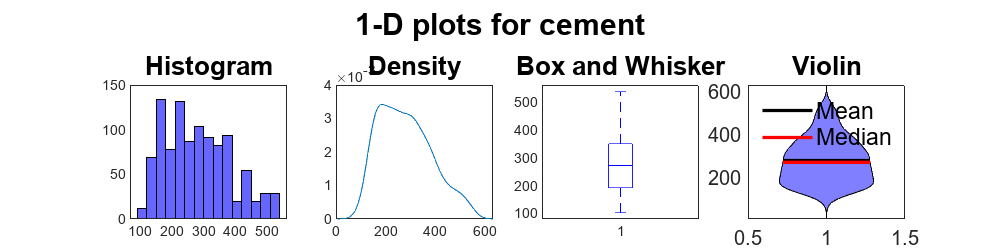

col = 'cement';

figure('Position', [0, 0, 800, 200]);
sgtitle(sprintf('1-D plots for %s', col), 'FontSize', 18, 'FontWeight', 'bold');

subplot(1, 4, 1);
histogram(df.(col), 'FaceColor', 'b');
title('Histogram', 'FontSize', 16);

subplot(1, 4, 2);
ksdensity(df.(col));
title('Density', 'FontSize', 16);

subplot(1, 4, 3);
boxplot(df.(col), 'Colors', 'b');
title('Box and Whisker', 'FontSize', 16);

subplot(1, 4, 4);
violin(df.(col), 'facecolor','b', 'linecolor', 'b', 'medc', 'r');
title('Violin', 'FontSize', 16);

### **Activity:** 

Create a series of 1-dimensional plots to visualize the distribution of concrete strength `csMPa` in MPa.

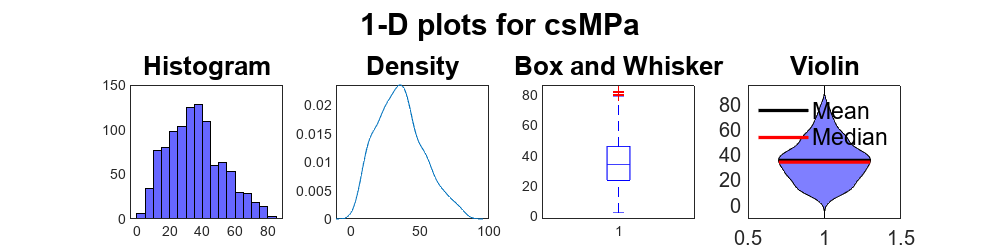

col = 'csMPa';

figure('Position', [0, 0, 800, 200]);
sgtitle(sprintf('1-D plots for %s', col), 'FontSize', 18, 'FontWeight', 'bold');

subplot(1, 4, 1);
histogram(df.(col), 'FaceColor', 'b');
title('Histogram', 'FontSize', 16);

subplot(1, 4, 2);
ksdensity(df.(col));
title('Density', 'FontSize', 16);

subplot(1, 4, 3);
boxplot(df.(col), 'Colors', 'b');
title('Box and Whisker', 'FontSize', 16);

subplot(1, 4, 4);
violin(df.(col), 'facecolor','b', 'linecolor', 'b', 'medc', 'r');
title('Violin', 'FontSize', 16);

## 2-D plots

2-dimensional plots are particularly useful to show correlations between two features. This could be useful to give you an idea of important features to predict an output with a machine learning model.

- **Line plots:** shows time series; since there is no time element in this dataset, this will not be shown here. To create a line plot, use plt.plot(data)

- **Scatter plots:** shows correlations between two features. Consider log scales for data that spans several orders of magnitude

- **Pairplots and jointplots:** seaborn plots that show both the distribution and correlations

- **Heatmap:** compute correlations between features using Pandas df.corr(). Highly correlated features are often redundant and slow down the analysis without improving results

- **Grouped 1-D plots:** distributions of a single column of data that are grouped based on an independent feature

**Scatter Plot:**

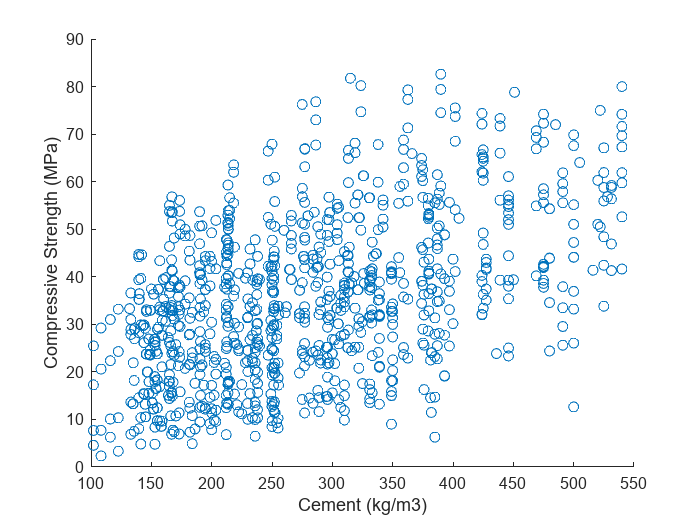

% Scatter plot
x = df.cement;
y = df.csMPa;

figure;
scatter(x,y);
xlabel('Cement (kg/m3)');
ylabel('Compressive Strength (MPa)');

**Pair Plot:**

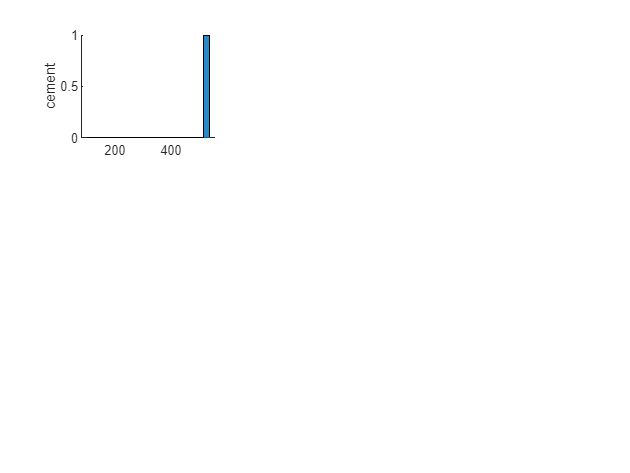

Error using matlab.graphics.chart.primitive.Histogram/set
Error setting property 'FaceColor' of class 'Histogram':
Invalid color name or hexadecimal color code. Valid names include: 'red', 'green', 'blue', 'cyan', 'magenta', 'yellow', 'black', 'white', and 'none'.
Valid hexadecimal color codes consist of '#' followed by three or six hexadecimal digits.

Error in matlab.graphics.chart.primitive.Histogram

Error in histogram (line 177)
    hObj = matlab.graphics.chart.pr

% Extract variables of interest
vars = {'cement', 'slag', 'csMPa'};
X = df{:, vars};

% Create pair plot
pairplot(X, vars, vars, 'both');

**Joint Plot**

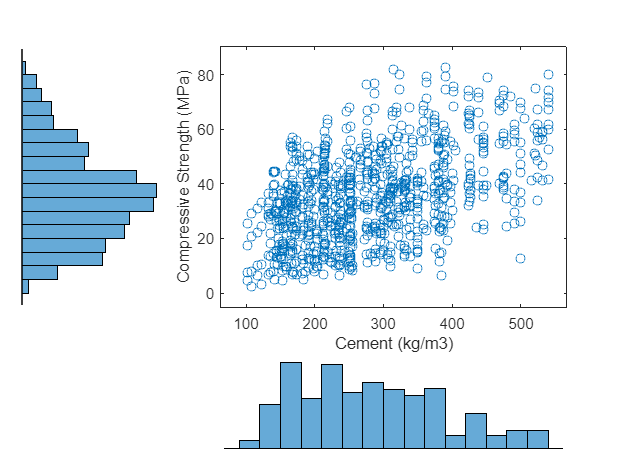

%Jointplot
x = df.cement;
y = df.csMPa;

figure;
scatterhist(x,y);
xlabel('Cement (kg/m3)');
ylabel('Compressive Strength (MPa)');

**Heatmap**

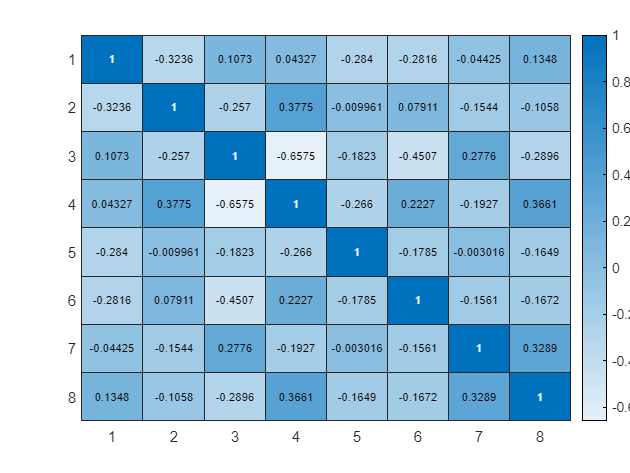

% Compute correlation matrix
corr_matrix = corr(df{:, 2:end});
%create a heatmap of the correlation matrix
%1.0 means exactly correlated, -1.0 means exactly inversely correlated, and 0.0 means no correlation
heatmap(corr_matrix, )